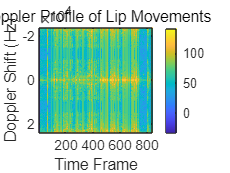

% 设置参数
fs = 48000; % 采样率，根据你的PCM文件设置
f_pilot = 24000; % 导频频率，根据论文设置
fft_size = 2048; % FFT大小，根据论文设置

% 读取PCM文件
pcm_file = 'test5.pcm'; % 替换成你的PCM文件路径
fid = fopen(pcm_file, 'r');
pcm_data = fread(fid, 'int16');
fclose(fid);

% 对pcm_data进行FFT变换
num_frames = floor(length(pcm_data) / fft_size);
fft_result = zeros(fft_size, num_frames);

for i = 1:num_frames
    frame = pcm_data((i-1)*fft_size + 1 : i*fft_size);
    fft_result(:, i) = fft(frame, fft_size);
end

% 计算信号梯度
gradient_matrix = zeros(size(fft_result));
for t = 2:num_frames
    gradient_matrix(:, t) = fft_result(:, t) - fft_result(:, t-1);
end

% 绘制多普勒轮廓
frequency_bins = (0:fft_size-1) * fs / fft_size;
doppler_shift = frequency_bins - f_pilot;

figure;
imagesc((1:num_frames), doppler_shift, 20*log10(abs(gradient_matrix)));
xlabel('Time Frame');
ylabel('Doppler Shift (Hz)');
title('Doppler Profile of Lip Movements');
colorbar;